**Cube Bot**

To perform inverted pendulum task. 

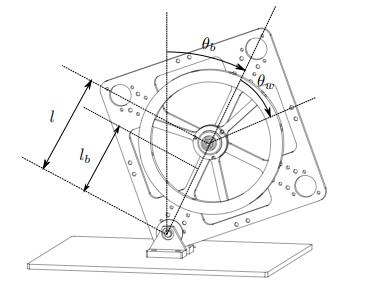

Fig1: Planar cube bot. (source: The Cubli: A cube that can jump up and balance, M Gajamohan, M Merz, I Thommen and R D'Andrea).

Planar cube bot is $15\times 15 \text{ $cm^2$}$ in size.


$$$l_b$ \text{: Distance between centre of mass of the pendulum body (rectangular body + other attached component like fastener, frame etc.) and pivot point.}$$



$$$l$ \text{: Distance between wheel axis and pivot.} $$



$${\theta_b} \text{: Angle between the diagonal of the pendulum joining pivot and vertical axis.}$$



$$\theta_w \text{: Rotational displacement of wheel with respect to pendulum body.}$$



$$$I_b$ \text{: Moment of inertia of the pendulum body about the pivotal axis perpendicular to the pendulum body.}$$



$$$I_w$ \text{: Moment of inertia of reaction wheel and motor rotor about the rotational axis of the motor.}$$



$$$C_b$ \text{: Dynamic friction coefficient of the pendulum body.}$$



$$$C_w$ \text{: Dynamic friction coefficient of wheel.}$$



$$T_m: \text{ Torque of motor}$$


**Mathematical Modeling of cube bot**

**Kinetic Energy**

Kinetic energy of pendulum body $T_b$:


$$T_b =  \frac{1}{2}I_b\dot{\theta_b}^2 $$


Wheel kinetic energy $$T_w$$:


$$
$T_w =   \frac{1}{2}m_w{(l.{\dot{\theta_b}})^2 + \frac{1}{2}I_w. ({\dot{\theta_b}} + \dot{\theta_w} )^2}$
$$
 

Cube bot total kinetic energy $T$:


$$T = T_b + T_w \\
T =  \frac{1}{2}I_b\dot{\theta_b}^2 +  \frac{1}{2}m_w{(l.{\dot{\theta_b}})^2 + \frac{1}{2}I_w. ({\dot{\theta_b}} + \dot{\theta_w} )^2}$$


**Potential energyy**

Potential energy of pendulum body  $V_b: $


$$V_b =  m_b. g. l_b. cos(\theta_b)$$


Potential energy of pendulum body  $V_w: $


$$V_w =  m_w. g. l. cos(\theta_b)$$


Total potential energy of cube bot $V:$


$$V = V_b + V_w \\
V = (m_b  l_b +  m_w l). g . cos(\theta_b)$$


Lagrangian function $L:$


$$L = T - V \\
L = \frac{1}{2}I_b\dot{\theta_b}^2 +  \frac{1}{2}m_w{(l.{\dot{\theta_b}})^2 + \frac{1}{2}I_w. ({\dot{\theta_b}} + \dot{\theta_w} )^2} -  (m_b  l_b +  m_w l). g . cos(\theta_b)$$



$${\frac{d}{dt}(\delta L/\delta{\dot{\theta_b}})} - \frac{\delta L}{\delta \theta_b} =   - C_b\dot{\theta_b}  \\


\frac{d}{dt}(I_b\dot{\theta_b} + m_wl^2\dot{\theta_b} + I_w(\dot{\theta_b} + \dot{\theta_w}))  - (m_bl_b + m_wl)gsin(\theta)  =  - C_b\dot{\theta_b}  \\


I_b\ddot{\theta_b} + m_wl^2\ddot{\theta_b} + I_w(\ddot{\theta_b} + \ddot{\theta_w})  - (m_bl_b + m_wl)gsin(\theta_b) =  - C_b\dot{\theta_b}  \\
$$



$${\frac{d}{dt}(\delta L/\delta{\dot{\theta_w}})} - \frac{\delta L}{\delta \theta_w} =  T_m - C_w\dot{\theta_w}  \\


\frac{d}{dt}( I_w (\dot{\theta_b} + \dot{\theta_w} ))  =  T_m - C_w\dot{\theta_w}\\

 I_w(\ddot{\theta_b} + \ddot{\theta_w} )  =  T_m - C_w\dot{\theta_w}

$$



$$$\ddot{\theta_b} =  \frac{ (m_bl_b + m_wl).g.sin(\theta_b)  - T_m + C_w\dot{\theta_w} - C_b\dot{\theta_b}}{I_b+ m_wl^2} \\$$$



$$\ddot{\theta_w} =\frac{ T_m - C_w\dot{\theta_w}}{I_w}  - \frac{ (m_bl_b + m_wl).g.sin(\theta_b)  - T_m + C_w\dot{\theta_w} - C_b\dot{\theta_b}}{I_b+ m_wl^2} \\$$


$T_m = K_m i$ , $K_m = 25.1e-3 N.mA^{-1}$ is torque constant of brushless DC motor.


$$\theta_b = x_1\\
\dot\theta_b = x_2, \ddot\theta_b = \dot{x_2} \\
\dot\theta_w = x_3, \ddot\theta_w = \dot{x_3}
$$



$$\dot{x_1} = x_2 \\

\dot{x_2} =  \frac{ (m_bl_b + m_wl).g.sin(x_1)  - T_m + C_w{x_3} - C_b{x_2}}{I_b+ m_wl^2}  \\

\dot{x_3} = \frac{ T_m - C_wx_3}{I_w}  - \frac{ (m_bl_b + m_wl).g.sin(x_1)  - T_m + C_wx_3 - C_bx_2}{I_b+ m_wl^2} \\$$


Linearized system at (0, 0, 0)


$$\pmatrix{\dot{x_1} \cr \dot{x_2} \cr \dot{x_3}}=\pmatrix{0 & 1 & 0  \cr \frac{(m_bl_b + m_wl)g}{I_b + m_wl^2}  & -\frac{C_b}{I_b + m_wl^2} & -\frac{C_w}{I_b + m_wl^2 \cr -\frac{(m_bl_b + m_wl)g}{I_b + m_wl^2} & \frac{C_b}{I_b + m_wl^2} & -\frac{C_w(I_w + I_b + m_wl^2)}{I_w(I__b + m_wl^2)}}\pmatrix{x_1 \cr x_2 \cr x_3}+

\pmatrix{ 0 \cr -\frac{1}{I_b + m_wl^2} \cr  \frac{(I_w + I_b + m_wl^2)}{I_w(I_b + m_wl^2)}}{T_m}$$


clc, clear, cla, clf;

global l lb Mb Mw Ib Iw Cb Cw g;
lb = 0.075; %m
l = 0.085;%m
Mb = 0.419; %kg
Mw = 0.204; %kg
Ib = 3.34e-3; %kg.m^2
Iw = 0.57e-3; %kg.m^2
Cb = 1.02e-3; %kg.m^2.s^-1
Cw = 0.05e-3; %kg.m^2.s^-1
g = 9.81; %ms^-2

global Integral tp
Integral = 0; tp = 0;

% initial condition
theta_b_0 = pi/4;
theta_w_0 = 0;
omega_w_0 = 70;

t_span = [0 20];
x_0 = [theta_b_0; 0; omega_w_0];


## PID for non-linear system

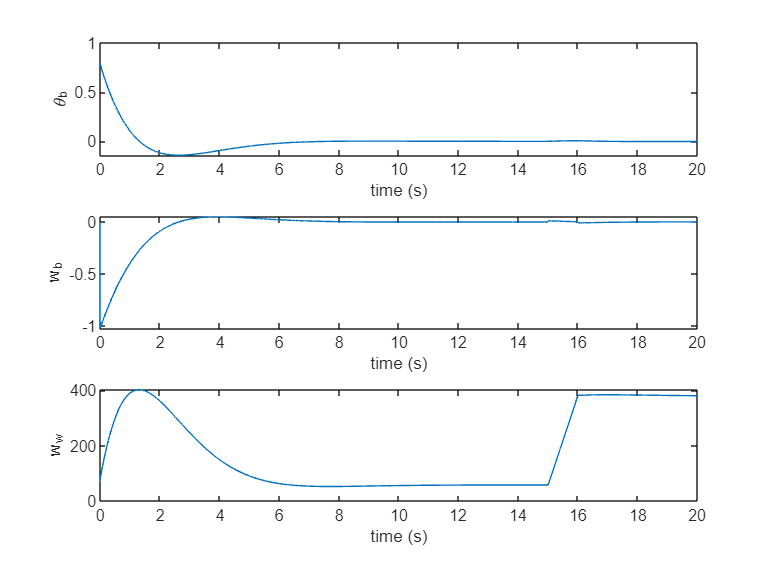


[t, X] = ode45(@(t,X)sysdyn(t, X),  t_span, x_0);

figure;
title("PID with non-linear system");
subplot(3,1,1)
plot(t,X(:,1));
ylabel('\theta_b')
xlabel('time (s)')

subplot(3,1,2)
plot(t,X(:,2));
ylabel('w_b')
xlabel('time (s)')

subplot(3,1,3)
plot(t,X(:,3));
ylabel('w_w')
xlabel("time (s)")

## PID for linear system

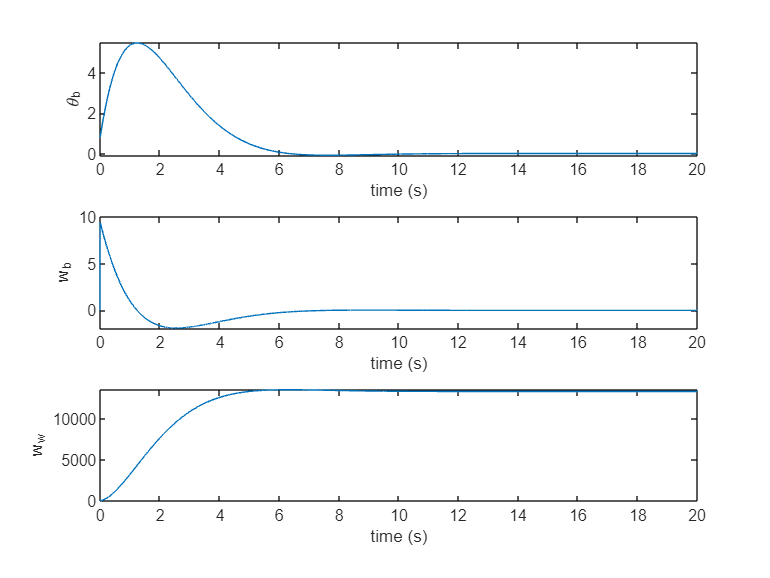

[t, X] = ode45(@(t,X)lin_sysdyn(t,X),  t_span, x_0);

figure;
title("PID with linear system");
subplot(3,1,1)
plot(t,X(:,1));
ylabel('\theta_b')
xlabel('time (s)')

subplot(3,1,2)
plot(t,X(:,2));
ylabel('w_b')
xlabel('time (s)')

subplot(3,1,3)
plot(t,X(:,3));
ylabel('w_w')
xlabel("time (s)")

## LQR

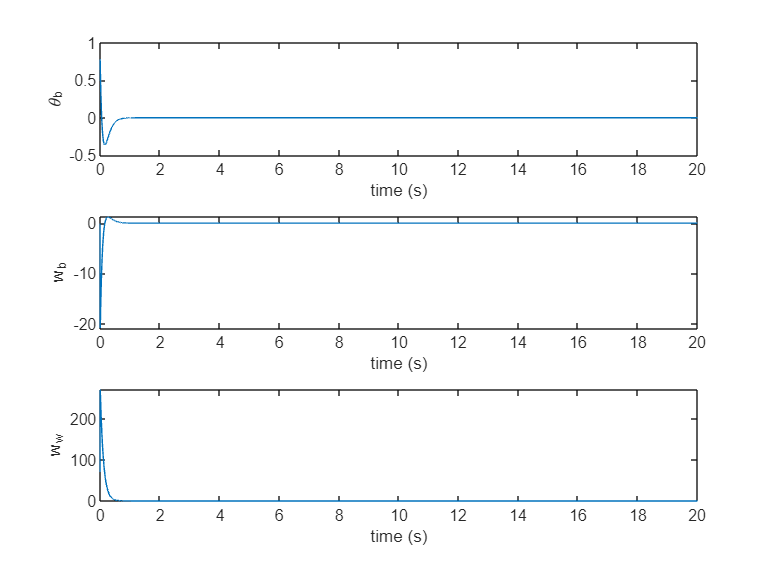

global K_lqr;
A = [0, 1, 0;...
    (Mb*lb + Mw*l)*g/(Ib + Mw*l*l), -Cb/(Ib + Mw*l*l), Cw/(Ib + Mw*l*l);...
    -(Mb*lb + Mw*l)*g/(Ib+Mw*l*l), Cb/(Ib+Mw*l*l), (Ib+ Iw+ Mw*l*l)*(-Cw)/(Iw*(Ib + Mw*l*l))];

B = [0; -1/(Ib + Mw*l*l); (Ib+ Iw+ Mw*l*l)/(Iw*(Ib + Mw*l*l))];

Q = [2 0  0; 0 5 0; 0 0 100];
R = 500;

K_lqr = lqr(A,B,Q,R);

[t, X] = ode45(@(t,X)sysdyn_lqr(t,X),  t_span, x_0);

figure;
title("PID with linear system");
subplot(3,1,1)
plot(t,X(:,1));
ylabel('\theta_b')
xlabel('time (s)')

subplot(3,1,2)
plot(t,X(:,2));
ylabel('w_b')
xlabel('time (s)')

subplot(3,1,3)
plot(t,X(:,3));
ylabel('w_w')
xlabel("time (s)")

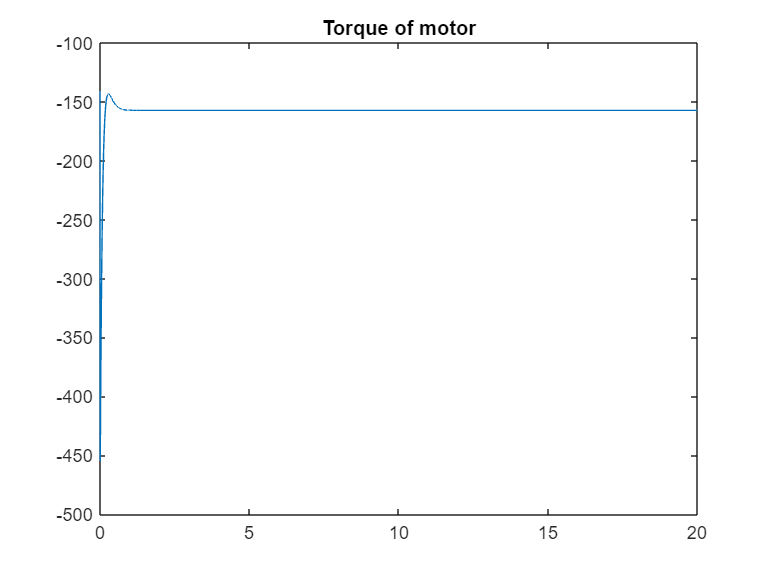


% torque in LQR
T_w = zeros(size(t));
for i=1:length(t)
    T_w(i) = control(t(i),X(i,:));
end

figure;
plot(t, T_w);
title("Torque of motor");

## Visulization

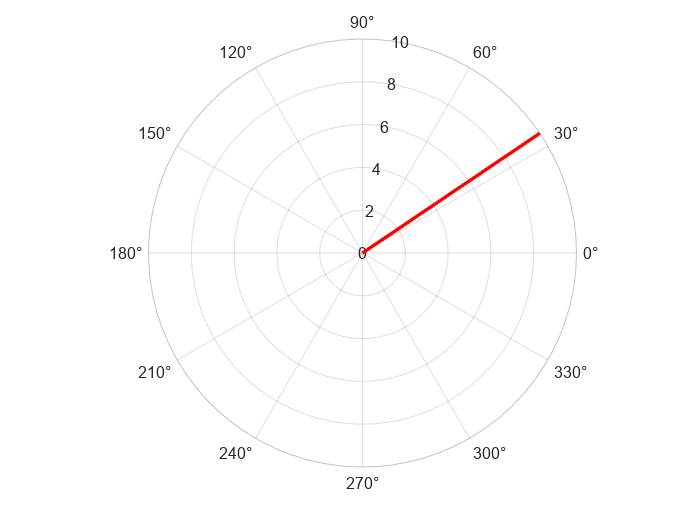

Array indices must be positive integers or logical values.

Error in topic_8>rotateBarPolar (line 186)
        theta = angular_position(i) ;

rotateBarPolar(X(:,1));

## Function

function dX = sysdyn(t,X)
   global l lb Mb Mw Ib Iw Cb Cw g
   disturbance = disturbance_angle(t);
   x1 = X(1) + disturbance; %theta_b
   x2 = X(2); % %theta_b_dot
   x3 = X(3); %theta_w_dot

   Torque = control(t,X);
   dX = zeros(4,1);
   dX = [x2;
            ((Mb*lb + Mw*l)*g*sin(x1) - Cb*x2 + Cw*x3 - Torque)/(Ib + Mw*l*l);
            ((Ib+ Iw+ Mw*l*l)*(Torque - Cw*x3))/(Iw*(Ib + Mw*l*l)) - ((Mb*lb + Mw*l)*g*sin(x1) - Cb*x2)/(Ib+Mw*l*l)];
end


function dX = lin_sysdyn(t,X)
   global l lb Mb Mw Ib Iw Cb Cw g

   x1 = X(1); %theta_b
   x2 = X(2); % theta_b_dot
   x3 = X(3); %theta_w_dot

   Torque = control(t,X);
   dX = [x2;
        ((Mb*lb + Mw*l)*g*x1 - Torque - Cb*x2 + Cw*x3)/(Ib + Mw*l*l);
        ((Ib+ Iw+ Mw*l*l)*(Torque - Cw*x3))/(Iw*(Ib + Mw*l*l)) - ((Mb*lb + Mw*l)*g*x1 - Cb*x2)/(Ib+Mw*l*l)];
end

function torque = control(t,X)
    kp = 20;
    ki = 10;
    kd = 15;
    des = 0;
    e = X(1) - des;
    de = X(2);
    global Integral tp
    Integral = (Integral+ki*e*(t-tp));
    tp = t;
    torque = kp*e + Integral +kd*de;
    %torque = 0;
end



% disturbance to body angle
function angle = disturbance_angle(t)
    if t > 15 && t < 16
         angle = pi/8;     
    else
        angle = 0;
    end
end

function dX = sysdyn_lqr(t,X)
   global l lb Mb Mw Ib Iw Cb Cw g K_lqr
   x1 = X(1);
   x2 = X(2);
   x3 = X(3);

   global K_lqr
   Torque = -K_lqr*X;
   dX = [x2;
        ((Mb*lb + Mw*l)*g*x1 - Torque - Cb*x2 + Cw*x3)/(Ib + Mw*l*l);
        ((Ib+ Iw+ Mw*l*l)*(Torque - Cw*x3))/(Iw*(Ib + Mw*l*l)) - ((Mb*lb + Mw*l)*g*x1 - Cb*x2)/(Ib+Mw*l*l)];
end

function rotateBarPolar(angular_position)
    
    figure;
    polaraxes;
    hold on;

    barLength = 10;
    theta = linspace(0, 2*pi, 100);
    barHandle = polarplot(theta, ones(size(theta)) * barLength, 'r-', 'LineWidth', 2);

  
    for i=1:length(angular_position)
        theta = angular_position(i);
        set(barHandle, 'ThetaData', [0, theta], 'RData', [0, barLength]);
        drawnow;
        pause(0.1);
    end

    hold off;
end